%% ========================================================================
%  UVP–PIT CARBON FLUX ANALYSIS
%
%  Workflow:
%    1. USER SETTINGS
%    2. VERIFY INPUT DATA
%    3. CALCULATE UVP PARTICLE SIZE DISTRIBUTION ACROSS DEPTH RANGE
%    4. SAVE AND VERIFY PSD DEPTH RANGE
%    5. CALCULATE PIT-OPTIMIZATION PSDs PER DEPTH INTERVAL
%    6. UVP-PIT OPTIMIZATION + JACKKNIFE FOR EACH DEPTH RANGE
%    7. UVP CARBON FLUX WITH DEPTH
% ========================================================================

%% ========================================================================
%  1. USER SETTINGS
% ========================================================================

fprintf('\n========================================\n');

fprintf('INPUTTING USER SETTINGS\n');

INPUTTING USER SETTINGS


fprintf('========================================\n');


% ------------------------------------------------------------------------
% CLEARING ENVIRONMENT
% ------------------------------------------------------------------------

clear;
close all;
clc;
driveLetter = 'F:';

% ------------------------------------------------------------------------
% FILE LOCATIONS
% ------------------------------------------------------------------------

dataFolder = fullfile( ...
    driveLetter, ...
    'Data Exports\Particle Characteristics');

saveDir = fullfile( ...
    driveLetter, ...
    'Data Exports\Particle Size Distribution');

saveFolder = fullfile( ...
    driveLetter, ...
    'Figure Repository');

scriptsFolder = fullfile( ...
    driveLetter, ...
    'White Docs\Matlab Processes\PhD Scripts');

datesFile = fullfile( ...
    driveLetter, ...
    'HOT_data_imports\project_dates.xlsx');

pitFile = fullfile( ...
    driveLetter, ...
    'HOT_data_imports\HOT_PIT_Carb_unQC.xlsx');

% ------------------------------------------------------------------------
% PROJECT SETTINGS
% ------------------------------------------------------------------------

% Current year for file names
year = 2026;

% Project to Use
projectNames = {'HOT'};

% Station to use
stationUse = 2;

% ------------------------------------------------------------------------
% UVP PARTICLE SIZE DISTRIBUTION (PSD) SETTINGS
% ------------------------------------------------------------------------

% Depth interval used for PSD calculation
depthRange = [0 500];

% Depth ranges used for PIT optimization
% shorter
pitDepthRanges = [
155 165
];

% Depth intervals for UVP flux calculation
% longer

% pitDepthRanges = [
%     (0:20:480)' (20:20:500)'
% ];


% Particle-size limits used to calculate the PSD
ESDmin = 0.1;
ESDmax = 26;

% Number of logarithmic particle-size bins
numBins = 46;

% ------------------------------------------------------------------------
% UVP–PIT OPTIMIZATION SETTINGS
% ------------------------------------------------------------------------

% Initial guess for the particle mass relationship:
%
%       mass = A * d^b
%
% The optimizer changes A and b to minimize the difference between
% UVP-derived flux and PIT measured flux.

initParams = [0.1, 1.5];

% Cruises to exclude from the UVP–PIT optimization.

excludeCruises = ["328"];

% If none should be excluded:
% excludeCruises = string.empty;

% Particle-size range used specifically for the UVP–PIT flux optimization.

Flux_ESDmin = ESDmin;
Flux_ESDmax = ESDmax;

% Carbon mass fraction:
% g C per g particle mass

POC_factor = 0.45;

% ------------------------------------------------------------------------
% JACKKNIFE SETTINGS
% ------------------------------------------------------------------------

% Number of random jackknife subsamples
nJackknife = 1000;

% Percentage of sample 
jackknifeFraction = 1/3;

% Random-number seed for reproducibility
rng(1);

% ------------------------------------------------------------------------
% PLOT SETTINGS
% ------------------------------------------------------------------------

plotType = 'All';

% Cruises to plot flux individually.

cruisesToPlot = {'321','322'};

% If you want the selected-cruise plot disabled:
% cruisesToPlot = {};


%% ========================================================================
%  2. VERIFY INPUT DATA
% ========================================================================

fprintf('\n========================================\n');

fprintf('VERIFYING INPUT DATA\n');

VERIFYING INPUT DATA


fprintf('========================================\n');


%% --- Check folders ------------------------------------------------------

fprintf('\nData folder:\n%s\n', dataFolder);


Data folder:
F:\Data Exports\Particle Characteristics


fprintf('Exists: %d\n', isfolder(dataFolder));

Exists: 1



fprintf('\nScripts folder:\n%s\n', scriptsFolder);


Scripts folder:
F:\White Docs\Matlab Processes\PhD Scripts


fprintf('Exists: %d\n', isfolder(scriptsFolder));

Exists: 1



fprintf('\nSave directory:\n%s\n', saveDir);


Save directory:
F:\Data Exports\Particle Size Distribution


fprintf('Exists: %d\n', isfolder(saveDir));

Exists: 1



fprintf('\nFigure repository:\n%s\n', saveFolder);


Figure repository:
F:\Figure Repository


fprintf('Exists: %d\n', isfolder(saveFolder));

Exists: 1




%% --- Check files --------------------------------------------------------

fprintf('\nDates file:\n%s\n', datesFile);


Dates file:
F:\HOT_data_imports\project_dates.xlsx


fprintf('Exists: %d\n', isfile(datesFile));

Exists: 1



fprintf('\nPIT file:\n%s\n', pitFile);


PIT file:
F:\HOT_data_imports\HOT_PIT_Carb_unQC.xlsx


fprintf('Exists: %d\n', isfile(pitFile));

Exists: 1




%% --- Check UVP data folder count ------------------------------------

uvpFiles = dir(fullfile(dataFolder, '*'));

% Remove folders from listing
uvpFiles = uvpFiles(~[uvpFiles.isdir]);

fprintf('\nNumber of files in UVP data folder: %d\n', length(uvpFiles));


Number of files in UVP data folder: 30



if ~isempty(uvpFiles)
    fprintf('\nFirst several files:\n');
    disp({uvpFiles(1:min(10,end)).name}');
else
    warning('No files were found in the UVP particle characteristics folder.');
end


First several files:


    {'GRADIENTS_4_particle_characterstics.mat'}
    {'GRADIENTS_5_particle_characterstics.mat'}
    {'HOT_321_particle_characterstics.mat'    }
    {'HOT_322_particle_characterstics.mat'    }
    {'HOT_323_particle_characterstics.mat'    }
    {'HOT_324_particle_characterstics.mat'    }
    {'HOT_325_particle_characterstics.mat'    }
    {'HOT_326_particle_characterstics.mat'    }
    {'HOT_327_particle_characterstics.mat'    }
    {'HOT_328_particle_characterstics.mat'    }





%% --- Check the project dates file ---------------------------------------

fprintf('\n========================================\n');

fprintf('READING PROJECT DATES\n');

READING PROJECT DATES


fprintf('========================================\n');


projDates = readtable(datesFile);

fprintf('Rows in project dates table: %d\n', height(projDates));

Rows in project dates table: 38


fprintf('Columns in project dates table: %d\n', width(projDates));

Columns in project dates table: 4



disp(projDates(1:min(5,height(projDates)), :));

    project    cruise     startDate        endDate   
    _______    ______    ____________    ____________

    {'HOT'}     321      {'06082020'}    {'11082020'}
    {'HOT'}     322      {'28082020'}    {'06092020'}
    {'HOT'}     323      {'25092020'}    {'30092020'}
    {'HOT'}     324      {'17112020'}    {'22112020'}
    {'HOT'}     325      {'17122020'}    {'21122020'}





%% --- Check the PIT file -------------------------------------------------

fprintf('\n========================================\n');

fprintf('READING PIT DATA\n');

READING PIT DATA


fprintf('========================================\n');


PIT_data = readtable(pitFile);

fprintf('Rows in PIT table: %d\n', height(PIT_data));

Rows in PIT table: 33


fprintf('Columns in PIT table: %d\n', width(PIT_data));

Columns in PIT table: 3



disp(PIT_data(1:min(5,height(PIT_data)), :));

    crn    carb    sd 
    ___    ____    ___

    319    20.2      5
    320    29.6    3.6
    321    32.2    2.7
    322    21.3    2.7
    323    25.5    5.2





%% --- Check required functions ------------------------------------------

fprintf('\n========================================\n');

fprintf('CHECKING REQUIRED FUNCTIONS\n');

CHECKING REQUIRED FUNCTIONS


fprintf('========================================\n');


fprintf('\nUVP5_PSD:\n');


UVP5_PSD:


which UVP5_PSD

F:\Scripts\Flux Code\UVP5_PSD.m



fprintf('\nUVP_PIT_Flux_Optimize:\n');


UVP_PIT_Flux_Optimize:


which UVP_PIT_Flux_Optimize

F:\Scripts\Flux Code\UVP_PIT_Flux_Optimize.m


%% ========================================================================
%  3. CALCULATE UVP PARTICLE SIZE DISTRIBUTION ACROSS DEPTH RANGE
% ========================================================================

fprintf('\n========================================\n');

fprintf('CALCULATING UVP PSD: %g-%g m\n', depthRange(1), depthRange(2));

CALCULATING UVP PSD: 0-500 m


fprintf('========================================\n');


% Make sure output directory exists
if ~exist(saveDir, 'dir')
    mkdir(saveDir);
end

% Run UVP particle-size distribution calculation
[PSD_data, PSD_slopes] = UVP5_PSD( ...
    dataFolder, ...
    projectNames, ...
    stationUse, ...
    depthRange, ...
    ESDmin, ...
    ESDmax, ...
    numBins, ...
    saveDir);

PSD computation completed.



fprintf('\nPSD calculation finished.\n');


PSD calculation finished.



%% --- Inspect PSD output -----------------------------------------------

fprintf('\n========================================\n');

fprintf('PSD OUTPUT\n');

PSD OUTPUT


fprintf('========================================\n');


fprintf('\nPSD_data:\n');


PSD_data:


whos PSD_data

  Name              Size              Bytes  Class    Attributes

  PSD_data      14812x11            2669639  table              




fprintf('\nFirst 10 rows of PSD_data:\n');


First 10 rows of PSD_data:


disp(PSD_data(1:min(10,height(PSD_data)), :));

    bin_center_mm    bin_width_mm    counts_per_liter_per_mm    project    cruise    cast    station       datetime_start           datetime_end        depthStart    depthEnd
    _____________    ____________    _______________________    _______    ______    ____    _______    ____________________    ____________________    __________    ________

       0.10623         0.012849                   0               "H"      "321"      5         2       08-Aug-2020 12:41:36    08-Aug-2020 12:41:36        0           500   
       0.11988         0.014501                   0               "H"      "321"      5         2   


fprintf('\nPSD_slopes:\n');


PSD_slopes:


whos PSD_slopes

  Name              Size            Bytes  Class    Attributes

  PSD_slopes      322x9             55781  table              




fprintf('\nFirst 10 rows of PSD_slopes:\n');


First 10 rows of PSD_slopes:


disp(PSD_slopes(1:min(10,height(PSD_slopes)), :));

    Project    Cruise    Cast    Station     Slope        DatetimeStart            DatetimeEnd         depthStart    depthEnd
    _______    ______    ____    _______    _______    ____________________    ____________________    __________    ________

      "H"      "321"       5        2       -3.0334    08-Aug-2020 12:41:36    08-Aug-2020 12:41:36        0           500   
      "H"      "321"       6        2       -3.0646    08-Aug-2020 15:37:50    08-Aug-2020 15:37:50        0           500   
      "H"      "321"       7        2       -3.1205    08-Aug-2020 18:21:30    08-Aug-2020 18:21:30        0           500   
      "H"      "321"       9        2       -3.6817    09-Aug-2

%% ========================================================================
%  4. SAVE AND VERIFY PSD DEPTH RANGE
% ========================================================================

fprintf('\n========================================\n');

fprintf('SAVING %g-%g m PSD\n', depthRange(1), depthRange(2));

SAVING 0-500 m PSD


fprintf('========================================\n');


% Create a dedicated PSD output folder
psdSaveDir = fullfile(saveDir, 'FullDepth');

if ~exist(psdSaveDir, 'dir')
    mkdir(psdSaveDir);
end

% File name
psdFile = fullfile(psdSaveDir, 'PSD_data_0_500_26.mat');

% File name
psdFile = fullfile(psdSaveDir, ...
    sprintf('PSD_data_%g_%g_%02d.mat', depthRange(1), depthRange(2), mod(year, 100)));

% Save PSD results
save(psdFile, 'PSD_data', 'PSD_slopes');

fprintf('\nPSD saved to:\n%s\n', psdFile);


PSD saved to:
F:\Data Exports\Particle Size Distribution\FullDepth\PSD_data_0_500_26.mat




%% --- Verify saved file -------------------------------------------------

fprintf('\n========================================\n');

fprintf('VERIFYING SAVED PSD\n');

VERIFYING SAVED PSD


fprintf('========================================\n');


fprintf('\nFile exists: %d\n', isfile(psdFile));


File exists: 1



% Check file information

fileInfo = dir(psdFile);

fprintf('File size: %.2f MB\n', fileInfo.bytes / 1024^2);

File size: 0.13 MB




%% --- PSD data checks -------------------------------------------------

fprintf('\n========================================\n');

fprintf('PSD DATA CHECKS\n');

PSD DATA CHECKS


fprintf('========================================\n');


fprintf('\nNumber of PSD rows: %d\n', height(PSD_data));


Number of PSD rows: 14812



fprintf('Number of unique cruises: %d\n', ...
    numel(unique(PSD_data.cruise)));

Number of unique cruises: 26



fprintf('Number of unique casts: %d\n', ...
    numel(unique(PSD_data.cast)));

Number of unique casts: 22



fprintf('Minimum particle size: %.4f mm\n', ...
    min(PSD_data.bin_center_mm));

Minimum particle size: 0.1062 mm



fprintf('Maximum particle size: %.4f mm\n', ...
    max(PSD_data.bin_center_mm));

Maximum particle size: 24.4751 mm



fprintf('Depth range represented:\n');

Depth range represented:


fprintf('Minimum depth start: %.1f m\n', min(PSD_data.depthStart));

Minimum depth start: 0.0 m


fprintf('Maximum depth end: %.1f m\n', max(PSD_data.depthEnd));

Maximum depth end: 500.0 m




%% --- List cruises ------------------------------------------------------

availableCruises = unique(PSD_data.cruise);

fprintf('\nAvailable cruises in PSD_data:\n');


Available cruises in PSD_data:


disp(availableCruises);

    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "328"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "349"
    "350"
    "351"
    "352"
    "353"
    "354"
    "355"
    "356"



%% ========================================================================
%  5. CALCULATE PIT-OPTIMIZATION PSDs PER DEPTH INTERVAL
% ========================================================================

fprintf('\n========================================\n');

fprintf('CALCULATING PIT DEPTH PSDs FOR OPTIMIZATION\n');

CALCULATING PIT DEPTH PSDs FOR OPTIMIZATION


fprintf('========================================\n');


% PSDs will be stored in cell arrays.

% Example:
%   PSD_PIT_all{1} = PSD for 145-155 m
%   PSD_PIT_all{2} = PSD for 155-165 m
%   etc.

PSD_PIT_all        = cell(size(pitDepthRanges,1),1);
PSD_slopes_PIT_all = cell(size(pitDepthRanges,1),1);

for d = 1:size(pitDepthRanges,1)


    pitDepthRange = pitDepthRanges(d,:);
    
    fprintf('\n----------------------------------------\n');
    fprintf('PIT optimization PSD: %d-%d m\n', ...
        pitDepthRange(1), pitDepthRange(2));
    fprintf('----------------------------------------\n');
    
    [PSD_PIT_all{d}, PSD_slopes_PIT_all{d}] = UVP5_PSD( ...
        dataFolder, ...
        projectNames, ...
        stationUse, ...
        pitDepthRange, ...
        ESDmin, ...
        ESDmax, ...
        numBins, ...
        saveDir);
   
    
    % ---------------------------------------------------------------
    % Check the PSD stats by depth interval
    % ---------------------------------------------------------------
    
    thisPSD = PSD_PIT_all{d};
    
    fprintf('Rows: %d\n', height(thisPSD));
    
    fprintf('Unique cruise-cast combinations: %d\n', ...
        numel(unique(strcat( ...
            string(thisPSD.cruise), "_", string(thisPSD.cast)))));
    
    fprintf('Particle size: %.4f to %.4f mm\n', ...
        min(thisPSD.bin_center_mm), ...
        max(thisPSD.bin_center_mm));
    
    fprintf('PSD count range: %.6g to %.6g\n', ...
        min(thisPSD.counts_per_liter_per_mm), ...
        max(thisPSD.counts_per_liter_per_mm));


end


----------------------------------------


PIT optimization PSD: 155-165 m


----------------------------------------


PSD computation completed.


Rows: 14306


Unique cruise-cast combinations: 311


Particle size: 0.1062 to 24.4751 mm


PSD count range: 0 to 1221.84


%% ========================================================================
%  6. UVP-PIT OPTIMIZATION + JACKKNIFE FOR EACH DEPTH RANGE
% ========================================================================

fprintf('\n========================================\n');

fprintf('UVP-PIT OPTIMIZATION + JACKKNIFE\n');

UVP-PIT OPTIMIZATION + JACKKNIFE


fprintf('========================================\n');


% Storage
optimizationResults = cell(size(pitDepthRanges,1),1);
jackknifeResults_all = cell(size(pitDepthRanges,1),1);
fluxStats_all = cell(size(pitDepthRanges,1),1);

uvpBinFlux_all = cell(size(pitDepthRanges,1),1);
uvpCastFlux_all = cell(size(pitDepthRanges,1),1);
uvpCruiseFlux_all = cell(size(pitDepthRanges,1),1);

% Summary table
optimizationSummary = table();

for d = 1:size(pitDepthRanges,1)


depthStart = pitDepthRanges(d,1);
depthEnd   = pitDepthRanges(d,2);

fprintf('\n========================================\n');
fprintf('DEPTH RANGE: %d-%d m\n', depthStart, depthEnd);
fprintf('========================================\n');

% PSD corresponding to this depth
thisPSD = PSD_PIT_all{d};

% Save temporary PSD file
thisPSDFile = fullfile( ...
    saveDir, ...
    sprintf('PSD_PIT_%d_%d.mat', ...
    depthStart, depthEnd));

save(thisPSDFile, 'thisPSD');

fprintf('PSD file:\n%s\n', thisPSDFile);


%% --- Run optimization + jackknife -------------------------------

[optParams, ...
    jackknifeResults, ...
    fluxStats, ...
    uvpCastFlux, ...
    uvpBinFlux, ...
    uvpCruiseFlux] = UVP_PIT_Flux_Optimize( ...
    thisPSDFile, ...
    pitFile, ...
    excludeCruises, ...
    initParams, ...
    POC_factor, ...
    Flux_ESDmin, ...
    Flux_ESDmax);


%% --- Store results -----------------------------------------------

optimizationResults{d} = optParams;

jackknifeResults_all{d} = jackknifeResults;

fluxStats_all{d} = fluxStats;

uvpBinFlux_all{d} = uvpBinFlux;

uvpCastFlux_all{d} = uvpCastFlux;

uvpCruiseFlux_all{d} = uvpCruiseFlux;


%% --- Add to summary table ----------------------------------------

newSummary = table( ...
    depthStart, ...
    depthEnd, ...
    optParams(1), ...
    optParams(2), ...
    fluxStats.jackknife_SE_A, ...
    fluxStats.jackknife_SE_b, ...
    fluxStats.jackknife_mean_A, ...
    fluxStats.jackknife_mean_b, ...
    fluxStats.jackknife_bias_A, ...
    fluxStats.jackknife_bias_b, ...
    fluxStats.R2_log_fit, ...
    fluxStats.p_log, ...
    fluxStats.nCruises, ...
    'VariableNames', ...
    { ...
    'depthStart', ...
    'depthEnd', ...
    'A', ...
    'b', ...
    'SE_A', ...
    'SE_b', ...
    'jackknife_mean_A', ...
    'jackknife_mean_b', ...
    'jackknife_bias_A', ...
    'jackknife_bias_b', ...
    'R2_log_fit', ...
    'p_log', ...
    'nCruises'});


optimizationSummary = ...
    [optimizationSummary; newSummary];

end

DEPTH RANGE: 155-165 m


PSD file:
F:\Data Exports\Particle Size Distribution\PSD_PIT_155_165.mat



Common UVP/PIT cruises used for optimization:
    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "350"
    "351"
    "352"
    "353"

Number of cruises used: 21

FULL-DATA UVP-PIT OPTIMIZATION
 
 Iteration   Func-count         f(x)         Procedure
     0            1          37.5389         
     1            3          32.7933         initial simplex
     2            5          25.6056         expand
     3            7          16.3521         expand
     4            9          4.85414         expand
     5           11          3.10338         reflect
     6           13          2.11649         contract outside
     7           15          2.11649         contract outside
     8           17          2.11649         contract inside
     9           18          2.11649       


%% --- Display optimization summary --------------------------------------

fprintf('\n========================================\n');

fprintf('OPTIMIZATION SUMMARY\n');

OPTIMIZATION SUMMARY


fprintf('========================================\n');


disp(optimizationSummary);

    depthStart    depthEnd       A          b         SE_A        SE_b      jackknife_mean_A    jackknife_mean_b    jackknife_bias_A    jackknife_bias_b    R2_log_fit      p_log       nCruises
    __________    ________    ________    ______    _________    _______    ________________    ________________    ________________    ________________    __________    __________    ________

       155          165       0.034139    1.7266    0.0040465    0.11052        0.034121             1.726             -0.000365           -0.012033         0.62906      1


%% --- Save optimization results -----------------------------------------

optimizationSaveFile = fullfile( ...
saveDir, ...
'UVP_PIT_Optimization_AllDepths.mat');

save( ...
optimizationSaveFile, ...
'optimizationSummary', ...
'optimizationResults', ...
'jackknifeResults_all', ...
'fluxStats_all', ...
'uvpBinFlux_all', ...
'uvpCastFlux_all', ...
'uvpCruiseFlux_all', ...
'pitDepthRanges');

fprintf('\nOptimization results saved to:\n%s\n', ...
optimizationSaveFile);


Optimization results saved to:
F:\Data Exports\Particle Size Distribution\UVP_PIT_Optimization_AllDepths.mat


%% ========================================================================
%  7. UVP CARBON FLUX WITH DEPTH
%% % ========================================================================

%  Flux calculated for 15 m depth intervals from 5-495 m
%  Mean flux plotted against depth
%  Standard deviation shown as horizontal error bars
%  100 m reference depth shown as red dashed line


%% 1. Extract flux statistics from each depth interval

nDepths = size(pitDepthRanges,1);

depthMidpoints = mean(pitDepthRanges,2);

fluxMean = nan(nDepths,1);
fluxSD   = nan(nDepths,1);


%% 2. Extract mean and SD flux for each depth interval

for d = 1:nDepths

    thisFlux = uvpCruiseFlux_all{d};

    % ---------------------------------------------------------------
    % Determine the flux column
    % ---------------------------------------------------------------

    if istable(thisFlux)

        % Try to identify the flux variable automatically
        variableNames = string(thisFlux.Properties.VariableNames);

        fluxIdx = contains( ...
            lower(variableNames), ...
            ["flux","uvp_flux"]);

        if any(fluxIdx)

            fluxVariable = variableNames(find(fluxIdx,1));

            fluxValues = thisFlux.(fluxVariable);

        else

            error( ...
                'Could not identify the flux variable in uvpCruiseFlux_all{%d}.', ...
                d);

        end

    else

        % If output is numeric
        fluxValues = thisFlux;

    end


    % ---------------------------------------------------------------
    % Remove invalid values
    % ---------------------------------------------------------------

    fluxValues = fluxValues( ...
        isfinite(fluxValues) & ...
        fluxValues > 0);


    % ---------------------------------------------------------------
    % Calculate mean and SD
    % ---------------------------------------------------------------

    if ~isempty(fluxValues)

        fluxMean(d) = mean(fluxValues);

        fluxSD(d) = std(fluxValues);

    end

end


%% 3. Create depth-flux table

depthFluxData = table( ...
    pitDepthRanges(:,1), ...
    pitDepthRanges(:,2), ...
    depthMidpoints, ...
    fluxMean, ...
    fluxSD, ...
    'VariableNames', ...
    {'depthStart','depthEnd','depth','fluxMean','fluxSD'});


%% 4. Display results

fprintf('\n========================================\n');

fprintf('UVP FLUX BY DEPTH\n');

UVP FLUX BY DEPTH


fprintf('========================================\n');


disp(depthFluxData);

    depthStart    depthEnd    depth    fluxMean    fluxSD
    __________    ________    _____    ________    ______

       155          165        160      26.771     8.4113



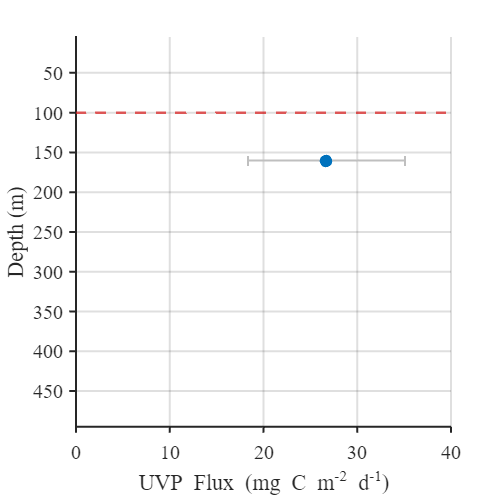



%% 5. Create figure

figure( ...
    'Color','w', ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

hold on;


%% 6. Plot 100 m reference line

yline( ...
    100, ...
    '--', ...
    'Color',[0.85 0.10 0.10], ...
    'LineWidth',1.5, ...
    'HandleVisibility','off');


%% 7. Plot horizontal standard deviation error bars

errorColor = [0.75 0.75 0.75];

for d = 1:nDepths

    if isfinite(fluxMean(d)) && ...
            isfinite(fluxSD(d))

        errorbar( ...
            fluxMean(d), ...
            depthMidpoints(d), ...
            fluxSD(d), ...
            'horizontal', ...
            'LineStyle','none', ...
            'Color',errorColor, ...
            'LineWidth',1.2, ...
            'CapSize',6, ...
            'HandleVisibility','off');

    end

end


%% 8. Plot flux points

validFlux = isfinite(fluxMean) & ...
            isfinite(depthMidpoints);

scatter( ...
    fluxMean(validFlux), ...
    depthMidpoints(validFlux), ...
    55, ...
    'MarkerFaceColor',[0.000 0.447 0.741], ...
    'MarkerEdgeColor','none');


%% 9. Reverse depth axis

set(gca, ...
    'YDir','reverse');


%% 10. Set depth limits

ylim([5 495]);


%% 11. Set x-axis limits

% Automatically determine a sensible x-axis limit
% while leaving some space to the right.

maxFlux = max( ...
    fluxMean(validFlux) + fluxSD(validFlux));

xlim([0 ceil(maxFlux/10)*10]);


%% 12. Axis labels

xlabel( ...
    'UVP Flux (mg C m^{-2} d^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);

ylabel( ...
    'Depth (m)', ...
    'FontName','Times New Roman', ...
    'FontSize',12);


%% 13. Axis formatting

ax = gca;

ax.FontName = 'Times New Roman';
ax.FontSize = 12;
ax.LineWidth = 1.2;

% Remove top and right axes
ax.Box = 'off';

% Put ticks outside
ax.TickDir = 'out';

ax.TickLength = [0.015 0.008];


%% 14. Depth ticks

yticks( ...
    0:50:500);


%% 15. Grid

grid on;


%% 16. Figure size

set(gcf, ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

set(gcf, ...
    'PaperUnits','inches', ...
    'PaperPosition',[0 0 6 6]);


%% 17. Save figure

fileName = 'UVP Flux by Depth';

exportgraphics( ...
    gcf, ...
    fullfile(saveFolder,[fileName '.png']), ...
    'Resolution',600);


hold off;

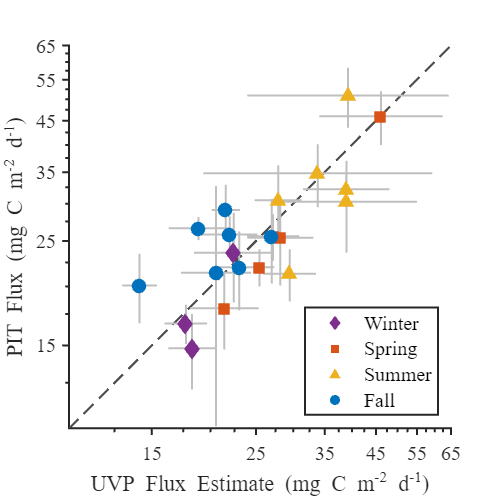

%% ========================================================================
%  8. UVP Flux vs PIT Flux
%% ========================================================================

% Log-log plot with log-space standard deviation error bars
% Season-specific colors and markers
% Includes dashed 1:1 reference line

%% 1. Calculate mean and standard deviation of UVP cast flux by cruise

[G, cruiseIDs] = findgroups(uvpCastFlux.cruise);

% Mean UVP flux in linear space
uvpMean = splitapply(@mean, uvpCastFlux.uvp_flux, G);

% Calculate SD in log10 space from individual casts
logUVP = log10(uvpCastFlux.uvp_flux);

% Replace invalid values with NaN
logUVP(~isfinite(logUVP)) = NaN;

uvpSDLog = splitapply(@std, logUVP, G);

% Convert cruise IDs to numeric
if iscell(cruiseIDs)
    cruiseNum = str2double(cruiseIDs);
elseif isstring(cruiseIDs)
    cruiseNum = str2double(cruiseIDs);
else
    cruiseNum = cruiseIDs;
end

% Create UVP summary table
uvpSummary = table( ...
    cruiseNum, ...
    uvpMean, ...
    uvpSDLog, ...
    'VariableNames', ...
    {'cruise','uvp_mean','uvp_sd_log'});


%% 2. Match UVP data to PIT data by cruise

matchedData = innerjoin( ...
    PIT_data, ...
    uvpSummary, ...
    'LeftKeys','crn', ...
    'RightKeys','cruise');


%% 3. Determine season from project dates

projCruise = projDates.cruise;

if iscell(projCruise)
    projCruise = cellfun(@str2double, projCruise);
elseif isstring(projCruise)
    projCruise = str2double(projCruise);
end

% Convert dates from DDMMYYYY format
startDate = datetime( ...
    projDates.startDate, ...
    'InputFormat','ddMMyyyy');

monthNum = month(startDate);

season = strings(height(projDates),1);

% Winter = December, January, February
season(monthNum == 12 | monthNum <= 2) = "Winter";

% Spring = March, April, May
season(monthNum >= 3 & monthNum <= 5) = "Spring";

% Summer = June, July, August
season(monthNum >= 6 & monthNum <= 8) = "Summer";

% Fall = September, October, November
season(monthNum >= 9 & monthNum <= 11) = "Fall";


% Season lookup table
seasonTable = table( ...
    projCruise, ...
    season, ...
    'VariableNames', ...
    {'cruise','season'});


%% 4. Add season information

matchedData = innerjoin( ...
    matchedData, ...
    seasonTable, ...
    'LeftKeys','crn', ...
    'RightKeys','cruise');


%% 5. Remove invalid values

valid = ~isnan(matchedData.uvp_mean) & ...
        ~isnan(matchedData.uvp_sd_log) & ...
        ~isnan(matchedData.carb) & ...
        ~isnan(matchedData.sd) & ...
        matchedData.uvp_mean > 0 & ...
        matchedData.carb > 0;

matchedData = matchedData(valid,:);


%% 6. Calculate log-space error bar limits

% -----------------------------
% UVP
% -----------------------------

uvpLogMean = log10(matchedData.uvp_mean);

uvpLogLow  = uvpLogMean - matchedData.uvp_sd_log;
uvpLogHigh = uvpLogMean + matchedData.uvp_sd_log;

uvpLow  = 10.^uvpLogLow;
uvpHigh = 10.^uvpLogHigh;


% -----------------------------
% PIT
% -----------------------------

% PIT has linear-space mean and SD.
% Convert mean +/- SD to log-space bounds.

pitLowLinear  = matchedData.carb - matchedData.sd;
pitHighLinear = matchedData.carb + matchedData.sd;

pitLowLinear(pitLowLinear <= 0) = NaN;

pitLogLow  = log10(pitLowLinear);
pitLogHigh = log10(pitHighLinear);

pitLow  = 10.^pitLogLow;
pitHigh = 10.^pitLogHigh;


%% 7. Define colors

% Winter = purple
winterColor = [0.494 0.184 0.556];

% Spring = orange
springColor = [0.850 0.325 0.098];

% Summer = yellow
summerColor = [0.929 0.694 0.125];

% Fall = blue
fallColor = [0.000 0.447 0.741];

% Light grey error bars
errorColor = [0.75 0.75 0.75];


%% 8. Create figure

figure( ...
    'Color','w', ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

hold on;


%% 9. Plot 1:1 reference line

loglog( ...
    [10 65], ...
    [10 65], ...
    '--', ...
    'Color',[0.3 0.3 0.3], ...
    'LineWidth',1.3, ...
    'HandleVisibility','off');


%% 10. Define season information

seasonNames = ["Winter","Spring","Summer","Fall"];

seasonColors = [
    winterColor
    springColor
    summerColor
    fallColor
];

% Winter = diamond
% Spring = square
% Summer = triangle
% Fall = circle

seasonMarkers = {'d','s','^','o'};


%% 11. Plot ALL error bars first

for i = 1:length(seasonNames)

    idx = matchedData.season == seasonNames(i);

    if any(idx)

        x = matchedData.uvp_mean(idx);
        y = matchedData.carb(idx);

        xLow = uvpLow(idx);
        xHigh = uvpHigh(idx);

        yLow = pitLow(idx);
        yHigh = pitHigh(idx);


        % Horizontal X error bars

        for j = 1:length(x)

            if xLow(j) > 0 && xHigh(j) > 0

                line( ...
                    [xLow(j) xHigh(j)], ...
                    [y(j) y(j)], ...
                    'Color',errorColor, ...
                    'LineWidth',1.2, ...
                    'HandleVisibility','off');

            end
        end


        % Vertical Y error bars

        for j = 1:length(x)

            if ~isnan(yLow(j)) && ...
                    yLow(j) > 0 && ...
                    yHigh(j) > 0

                line( ...
                    [x(j) x(j)], ...
                    [yLow(j) yHigh(j)], ...
                    'Color',errorColor, ...
                    'LineWidth',1.2, ...
                    'HandleVisibility','off');

            end
        end

    end
end


%% 12. Plot ALL data points after error bars

for i = 1:length(seasonNames)

    idx = matchedData.season == seasonNames(i);

    if any(idx)

        x = matchedData.uvp_mean(idx);
        y = matchedData.carb(idx);

        c = seasonColors(i,:);
        marker = seasonMarkers{i};

        scatter( ...
            x, y, ...
            75, ...
            'Marker',marker, ...
            'MarkerFaceColor',c, ...
            'MarkerEdgeColor','none', ...
            'DisplayName',seasonNames(i));

    end
end


%% 13. Log-log axes

set(gca, ...
    'XScale','log', ...
    'YScale','log');


%% 14. Set axis limits

xlim([10 65]);
ylim([10 65]);

axis square;


%% 15. Set major tick locations

majorTicks = [15 25 35 45 55 65];

xticks(majorTicks);
yticks(majorTicks);


%% 16. Add minor ticks

% Minor ticks every 2.5 units
minorTicks = 12.5:2.5:65;

% Remove major tick positions
minorTicks = setdiff(minorTicks,majorTicks);

ax = gca;

ax.XAxis.MinorTickValues = minorTicks;
ax.YAxis.MinorTickValues = minorTicks;

ax.XMinorTick = 'on';
ax.YMinorTick = 'on';


%% 17. Put ticks outside the axes

ax.TickDir = 'out';

ax.TickLength = [0.015 0.008];


%% 18. Axis labels

xlabel( ...
    'UVP Flux Estimate (mg C m^{-2} d^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);

ylabel( ...
    'PIT Flux (mg C m^{-2} d^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);


%% 19. Formatting

ax.FontName = 'Times New Roman';
ax.FontSize = 12;
ax.LineWidth = 1.2;

% Remove top and right axes
ax.Box = 'off';

% No grid
grid off;


%% 20. Legend

lgd = legend('Location','southeast');

lgd.FontName = 'Times New Roman';
lgd.FontSize = 12;
lgd.Box = 'on';


%% 21. Set figure size explicitly

set(gcf, ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

set(gcf, ...
    'PaperUnits','inches', ...
    'PaperPosition',[0 0 6 6]);


%% 22. Save figure as PNG

fileName = 'UVP vs. PIT Flux by Season';

exportgraphics( ...
    gcf, ...
    fullfile(saveFolder,[fileName '.png']), ...
    'Resolution',600);


%% 23. Finish

hold off;

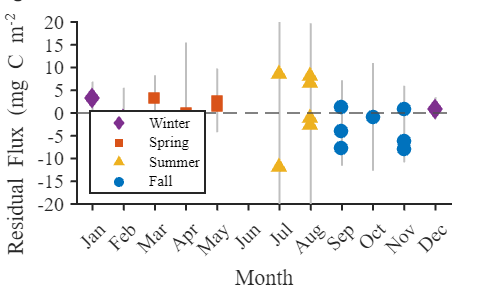

%% ======================================================================== 
% 9. UVP vs PIT Flux Residual by Month
%% ========================================================================

% Residual = UVP Flux Estimate - PIT Flux
% Propagated uncertainty = sqrt(UVP uncertainty^2 + PIT SD^2)
% Colored by season

%% 1. Calculate mean UVP flux by cruise

[G, cruiseIDs] = findgroups(uvpCastFlux.cruise);

% Mean UVP flux in linear space
uvpMean = splitapply(@mean, uvpCastFlux.uvp_flux, G);

% Calculate SD of UVP casts in log10 space
logUVP = log10(uvpCastFlux.uvp_flux);
logUVP(~isfinite(logUVP)) = NaN;

uvpSDLog = splitapply(@std, logUVP, G);

% Convert cruise IDs to numeric
if iscell(cruiseIDs)
    cruiseNum = str2double(cruiseIDs);
elseif isstring(cruiseIDs)
    cruiseNum = str2double(cruiseIDs);
else
    cruiseNum = cruiseIDs;
end

% UVP summary table
uvpSummary = table( ...
    cruiseNum, ...
    uvpMean, ...
    uvpSDLog, ...
    'VariableNames', ...
    {'cruise','uvp_mean','uvp_sd_log'});


%% 2. Match UVP data to PIT data by cruise

matchedData = innerjoin( ...
    PIT_data, ...
    uvpSummary, ...
    'LeftKeys','crn', ...
    'RightKeys','cruise');


%% 3. Match project dates to cruises

projCruise = projDates.cruise;

if iscell(projCruise)
    projCruise = cellfun(@str2double, projCruise);
elseif isstring(projCruise)
    projCruise = str2double(projCruise);
end

% Convert project start dates from DDMMYYYY
startDate = datetime( ...
    projDates.startDate, ...
    'InputFormat','ddMMyyyy');

% Extract month
monthNum = month(startDate);


%% 4. Determine season

season = strings(height(projDates),1);

% Winter = December, January, February
season(monthNum == 12 | monthNum <= 2) = "Winter";

% Spring = March, April, May
season(monthNum >= 3 & monthNum <= 5) = "Spring";

% Summer = June, July, August
season(monthNum >= 6 & monthNum <= 8) = "Summer";

% Fall = September, October, November
season(monthNum >= 9 & monthNum <= 11) = "Fall";


% Create date/season lookup table
seasonTable = table( ...
    projCruise, ...
    monthNum, ...
    season, ...
    'VariableNames', ...
    {'cruise','month','season'});


%% 5. Add month and season information

matchedData = innerjoin( ...
    matchedData, ...
    seasonTable, ...
    'LeftKeys','crn', ...
    'RightKeys','cruise');


%% 6. Remove invalid values

valid = ~isnan(matchedData.uvp_mean) & ...
        ~isnan(matchedData.uvp_sd_log) & ...
        ~isnan(matchedData.carb) & ...
        ~isnan(matchedData.sd) & ...
        matchedData.uvp_mean > 0 & ...
        matchedData.carb > 0;

matchedData = matchedData(valid,:);


%% 7. Calculate residual

% Residual = UVP - PIT

matchedData.residual = ...
    matchedData.uvp_mean - matchedData.carb;


%% 8. Calculate propagated uncertainty

% UVP uncertainty is in log10 space.
% Convert the log-space SD into linear-space bounds.

uvpLogMean = log10(matchedData.uvp_mean);

uvpLogLow  = uvpLogMean - matchedData.uvp_sd_log;
uvpLogHigh = uvpLogMean + matchedData.uvp_sd_log;

uvpLow  = 10.^uvpLogLow;
uvpHigh = 10.^uvpLogHigh;

% Convert asymmetric UVP uncertainty to a symmetric
% linear-space uncertainty.

uvpSDLinear = (uvpHigh - uvpLow) ./ 2;


% PIT SD is already in linear space

pitSDLinear = matchedData.sd;


% Propagate independent uncertainties:
%
% SD_residual = sqrt(SD_UVP^2 + SD_PIT^2)

matchedData.residualSD = sqrt( ...
    uvpSDLinear.^2 + ...
    pitSDLinear.^2);


%% 9. Define colors

% Winter = purple
winterColor = [0.494 0.184 0.556];

% Spring = orange
springColor = [0.850 0.325 0.098];

% Summer = yellow
summerColor = [0.929 0.694 0.125];

% Fall = blue
fallColor = [0.000 0.447 0.741];

% Light grey error bars
errorColor = [0.75 0.75 0.75];


%% 10. Create figure

figure( ...
    'Color','w', ...
    'Units','inches', ...
    'Position',[1 1 6 3.5]);

hold on;


%% 11. Add zero reference line

yline( ...
    0, ...
    '--', ...
    'Color',[0.3 0.3 0.3], ...
    'LineWidth',1.3, ...
    'HandleVisibility','off');


%% 12. Define season information

seasonNames = ["Winter","Spring","Summer","Fall"];

seasonColors = [
    winterColor
    springColor
    summerColor
    fallColor
];

% Winter = diamond
% Spring = square
% Summer = triangle
% Fall = circle

seasonMarkers = {'d','s','^','o'};


%% 13. Plot propagated error bars first

% This places the error bars behind the data points.
% Error bars have no caps.

for i = 1:length(seasonNames)

    idx = matchedData.season == seasonNames(i);

    if any(idx)

        x = matchedData.month(idx);
        y = matchedData.residual(idx);
        ysd = matchedData.residualSD(idx);

        for j = 1:length(x)

            if ~isnan(ysd(j))

                line( ...
                    [x(j) x(j)], ...
                    [y(j)-ysd(j) y(j)+ysd(j)], ...
                    'Color',errorColor, ...
                    'LineWidth',1.2, ...
                    'HandleVisibility','off');

            end

        end
    end
end


%% 14. Plot data points

for i = 1:length(seasonNames)

    idx = matchedData.season == seasonNames(i);

    if any(idx)

        x = matchedData.month(idx);
        y = matchedData.residual(idx);

        c = seasonColors(i,:);
        marker = seasonMarkers{i};

        scatter( ...
            x, y, ...
            75, ...
            'Marker',marker, ...
            'MarkerFaceColor',c, ...
            'MarkerEdgeColor','none', ...
            'DisplayName',seasonNames(i));

    end
end


%% 15. Set axis limits

% Slightly extend the x-axis so January is not directly
% against the y-axis.

xlim([0.5 12.5]);

ylim([-20 20]);


%% 16. X-axis months

xticks(1:12);

xticklabels({ ...
    'Jan','Feb','Mar','Apr','May','Jun', ...
    'Jul','Aug','Sep','Oct','Nov','Dec'});


%% 17. Y-axis ticks

yticks(-20:5:20);


%% 18. Axis labels

xlabel( ...
    'Month', ...
    'FontName','Times New Roman', ...
    'FontSize',12);

ylabel( ...
    'Residual Flux (mg C m^{-2} d^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);


%% 19. Formatting

ax = gca;

ax.FontName = 'Times New Roman';
ax.FontSize = 12;
ax.LineWidth = 1.2;

% Remove top and right axes
ax.Box = 'off';

% Ticks outside
ax.TickDir = 'out';

ax.TickLength = [0.015 0.008];

% Grid on
grid off;


%% 20. Legend

lgd = legend('Location','southwest');

lgd.FontName = 'Times New Roman';
lgd.FontSize = 9;
lgd.Box = 'on';


%% 21. Set figure size

set(gcf, ...
    'Units','inches', ...
    'Position',[1 1 6 3.5]);

set(gcf, ...
    'PaperUnits','inches', ...
    'PaperPosition',[0 0 6 3.5]);


%% 22. Save figure as PNG

fileName = 'UVP vs. PIT Flux Residual by Month';

exportgraphics( ...
    gcf, ...
    fullfile(saveFolder,[fileName '.png']), ...
    'Resolution',600);


%% 23. Finish

hold off;

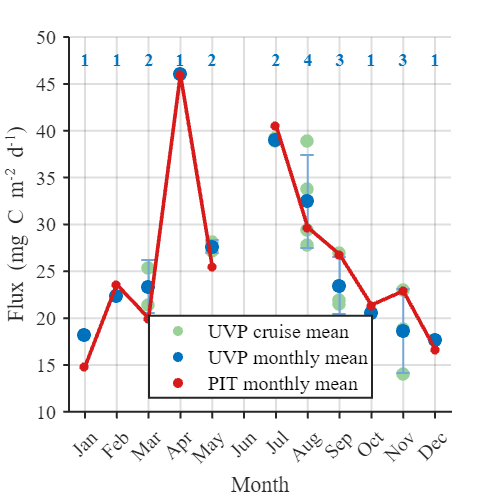

%% ======================================================================== 
% 10. Monthly PIT and UVP Carbon Flux
%% ========================================================================

% PIT:
%   Monthly mean shown as small red dots
%   Red line connecting monthly means
%   Only includes cruises with matching UVP data
%
% UVP:
%   Individual cruise means shown as light green dots
%   Monthly mean shown as blue dots
%   Number of cruises shown at the top of the graph



%% 1. Calculate mean UVP flux for each cruise

[G, cruiseIDs] = findgroups(uvpCastFlux.cruise);

% Mean UVP flux for each cruise
uvpCruiseMean = splitapply(@mean, uvpCastFlux.uvp_flux, G);

% Convert cruise IDs to numeric
if iscell(cruiseIDs)
    cruiseNum = str2double(cruiseIDs);
elseif isstring(cruiseIDs)
    cruiseNum = str2double(cruiseIDs);
else
    cruiseNum = cruiseIDs;
end

% Create cruise-level UVP table
uvpCruiseData = table( ...
    cruiseNum, ...
    uvpCruiseMean, ...
    'VariableNames', ...
    {'cruise','uvp_flux'});


%% 2. Match UVP cruise means with project dates

projCruise = projDates.cruise;

if iscell(projCruise)
    projCruise = cellfun(@str2double, projCruise);
elseif isstring(projCruise)
    projCruise = str2double(projCruise);
end

% Convert project start dates
startDate = datetime( ...
    projDates.startDate, ...
    'InputFormat','ddMMyyyy');

% Extract month
projMonth = month(startDate);

% Create cruise/month lookup table
dateTable = table( ...
    projCruise, ...
    projMonth, ...
    'VariableNames', ...
    {'cruise','month'});

% Add month information to UVP cruise means
uvpCruiseData = innerjoin( ...
    uvpCruiseData, ...
    dateTable, ...
    'Keys','cruise');


%% 3. Remove invalid UVP values

validUVP = ~isnan(uvpCruiseData.uvp_flux) & ...
           uvpCruiseData.uvp_flux > 0;

uvpCruiseData = uvpCruiseData(validUVP,:);


%% 4. Calculate monthly UVP statistics

[uvpMonthGroups, uvpMonths] = findgroups( ...
    uvpCruiseData.month);

% Monthly UVP mean
uvpMonthlyMean = splitapply( ...
    @mean, ...
    uvpCruiseData.uvp_flux, ...
    uvpMonthGroups);

% Monthly UVP SD
uvpMonthlySD = splitapply( ...
    @std, ...
    uvpCruiseData.uvp_flux, ...
    uvpMonthGroups);

% Number of cruises contributing to each month
uvpN = splitapply( ...
    @numel, ...
    uvpCruiseData.uvp_flux, ...
    uvpMonthGroups);


%% 5. Match PIT data to the UVP cruises

% First match PIT data to project dates
pitDataWithMonth = innerjoin( ...
    PIT_data, ...
    dateTable, ...
    'LeftKeys','crn', ...
    'RightKeys','cruise');


% Keep ONLY PIT cruises that have a matching UVP cruise

matchedUVPCruises = unique(uvpCruiseData.cruise);

pitDataWithMonth = pitDataWithMonth( ...
    ismember(pitDataWithMonth.crn,matchedUVPCruises),:);


%% 6. Remove invalid PIT values

validPIT = ~isnan(pitDataWithMonth.carb);

pitDataWithMonth = pitDataWithMonth(validPIT,:);


%% 7. Calculate monthly PIT means

[pitMonthGroups, pitMonths] = findgroups( ...
    pitDataWithMonth.month);

pitMonthlyMean = splitapply( ...
    @mean, ...
    pitDataWithMonth.carb, ...
    pitMonthGroups);


%% 8. Define colors

% PIT = red
pitColor = [0.850 0.100 0.100];

% Individual UVP cruises = light green
uvpIndividualColor = [0.60 0.82 0.60];

% UVP monthly mean = blue
uvpMeanColor = [0.000 0.447 0.741];

% UVP error bars = lighter blue
uvpErrorColor = [0.45 0.65 0.85];


%% 9. Create figure

figure( ...
    'Color','w', ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

hold on;


%% 10. Plot individual UVP cruise means

scatter( ...
    uvpCruiseData.month, ...
    uvpCruiseData.uvp_flux, ...
    65, ...
    'MarkerFaceColor',uvpIndividualColor, ...
    'MarkerEdgeColor','none', ...
    'DisplayName','UVP cruise mean');


%% 11. Plot UVP monthly SD error bars

for i = 1:length(uvpMonths)

    x = uvpMonths(i);
    y = uvpMonthlyMean(i);
    ysd = uvpMonthlySD(i);

    if ~isnan(ysd)

        errorbar( ...
            x, ...
            y, ...
            ysd, ...
            'LineStyle','none', ...
            'Color',uvpErrorColor, ...
            'LineWidth',1.3, ...
            'CapSize',8, ...
            'HandleVisibility','off');

    end
end


%% 12. Plot UVP monthly means

scatter( ...
    uvpMonths, ...
    uvpMonthlyMean, ...
    70, ...
    'MarkerFaceColor',uvpMeanColor, ...
    'MarkerEdgeColor','none', ...
    'DisplayName','UVP monthly mean');


%% 13. Determine y-axis limits

allFlux = [ ...
    uvpCruiseData.uvp_flux; ...
    uvpMonthlyMean + uvpMonthlySD; ...
    uvpMonthlyMean - uvpMonthlySD; ...
    pitMonthlyMean];

allFlux = allFlux(~isnan(allFlux));

yMin = floor(min(allFlux) / 5) * 5;
yMax = ceil(max(allFlux) / 5) * 5;

yMin = max(0,yMin);
yMax = max(yMax,1);

ylim([yMin yMax]);


%% 14. Plot number of cruises at top of graph

for i = 1:length(uvpMonths)

    text( ...
        uvpMonths(i), ...
        yMax - 0.03*(yMax-yMin), ...
        num2str(uvpN(i)), ...
        'Color',uvpMeanColor, ...
        'FontName','Times New Roman', ...
        'FontSize',11, ...
        'FontWeight','bold', ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','top', ...
        'HandleVisibility','off');

end


%% 15. Plot monthly PIT means

% Create a full 12-month array so months with no data remain as NaN
pitMonthlyFull = nan(1,12);

for i = 1:length(pitMonths)
    pitMonthlyFull(pitMonths(i)) = pitMonthlyMean(i);
end

% Plot red line -- NaN values create gaps where there is no data
plot( ...
    1:12, ...
    pitMonthlyFull, ...
    '-', ...
    'Color',pitColor, ...
    'LineWidth',2.2, ...
    'HandleVisibility','off');

% Plot small PIT dots only where data exist
validPitMonths = ~isnan(pitMonthlyFull);

scatter( ...
    (1:12)', ...
    pitMonthlyFull', ...
    30, ...
    'MarkerFaceColor',pitColor, ...
    'MarkerEdgeColor','none', ...
    'DisplayName','PIT monthly mean');



%% 16. Set x-axis limits

xlim([0.5 12.5]);


%% 17. X-axis months

xticks(1:12);

xticklabels({ ...
    'Jan','Feb','Mar','Apr','May','Jun', ...
    'Jul','Aug','Sep','Oct','Nov','Dec'});


%% 18. Axis labels

xlabel( ...
    'Month', ...
    'FontName','Times New Roman', ...
    'FontSize',12);

ylabel( ...
    'Flux (mg C m^{-2} d^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);


%% 19. Formatting

ax = gca;

ax.FontName = 'Times New Roman';
ax.FontSize = 12;
ax.LineWidth = 1.2;

% Remove top and right axes
ax.Box = 'off';

% Ticks outside
ax.TickDir = 'out';

ax.TickLength = [0.015 0.008];

% Grid on
grid on;

%% 20. Legend

lgd = legend( ...
    'Location','south');

lgd.FontName = 'Times New Roman';
lgd.FontSize = 12;
lgd.Box = 'on';


%% 21. Set figure size

set(gcf, ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

set(gcf, ...
    'PaperUnits','inches', ...
    'PaperPosition',[0 0 6 6]);


%% 22. Save figure

fileName = 'Monthly UVP and PIT Carbon Flux';

exportgraphics( ...
    gcf, ...
    fullfile(saveFolder,[fileName '.png']), ...
    'Resolution',600);


%% 23. Finish

hold off;

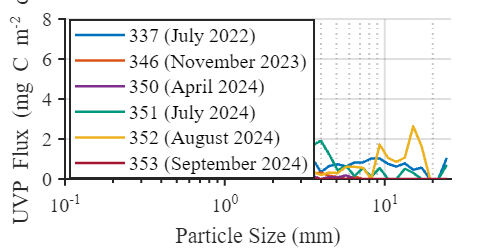

INPUTTING USER SETTINGS


VERIFYING INPUT DATA



Data folder:
F:\Data Exports\Particle Characteristics


Exists: 1



Scripts folder:
F:\White Docs\Matlab Processes\PhD Scripts


Exists: 1



Save directory:
F:\Data Exports\Particle Size Distribution


Exists: 1



Figure repository:
F:\Figure Repository


Exists: 1



Dates file:
F:\HOT_data_imports\project_dates.xlsx


Exists: 1



PIT file:
F:\HOT_data_imports\HOT_PIT_Carb_unQC.xlsx


Exists: 1



Number of files in UVP data folder: 30



First several files:


    {'GRADIENTS_4_particle_characterstics.mat'}
    {'GRADIENTS_5_particle_characterstics.mat'}
    {'HOT_321_particle_characterstics.mat'    }
    {'HOT_322_particle_characterstics.mat'    }
    {'HOT_323_particle_characterstics.mat'    }
    {'HOT_324_particle_characterstics.mat'    }
    {'HOT_325_particle_characterstics.mat'    }
    {'HOT_326_particle_characterstics.mat'    }
    {'HOT_327_particle_characterstics.mat'    }
    {'HOT_328_particle_characterstics.mat'    }



READING PROJECT DATES


Rows in project dates table: 38


Columns in project dates table: 4


    project    cruise     startDate        endDate   
    _______    ______    ____________    ____________

    {'HOT'}     321      {'06082020'}    {'11082020'}
    {'HOT'}     322      {'28082020'}    {'06092020'}
    {'HOT'}     323      {'25092020'}    {'30092020'}
    {'HOT'}     324      {'17112020'}    {'22112020'}
    {'HOT'}     325      {'17122020'}    {'21122020'}



READING PIT DATA


Rows in PIT table: 33


Columns in PIT table: 3


    crn    carb    sd 
    ___    ____    ___

    319    20.2      5
    320    29.6    3.6
    321    32.2    2.7
    322    21.3    2.7
    323    25.5    5.2



CHECKING REQUIRED FUNCTIONS



UVP5_PSD:


F:\Scripts\Flux Code\UVP5_PSD.m



UVP_PIT_Flux_Optimize:


F:\Scripts\Flux Code\UVP_PIT_Flux_Optimize.m


CALCULATING UVP PSD: 0-500 m


PSD computation completed.



PSD calculation finished.


PSD OUTPUT



PSD_data:


  Name              Size              Bytes  Class    Attributes

  PSD_data      14812x11            2669639  table              




First 10 rows of PSD_data:


    bin_center_mm    bin_width_mm    counts_per_liter_per_mm    project    cruise    cast    station       datetime_start           datetime_end        depthStart    depthEnd
    _____________    ____________    _______________________    _______    ______    ____    _______    ____________________    ____________________    __________    ________

       0.10623         0.012849                   0               "H"      "321"      5         2       08-Aug-2020 12:41:36    08-Aug-2020 12:41:36        0           500   
       0.11988         0.014501                   0               "H"      "321"      5         2   


PSD_slopes:


  Name              Size            Bytes  Class    Attributes

  PSD_slopes      322x9             55781  table              




First 10 rows of PSD_slopes:


    Project    Cruise    Cast    Station     Slope        DatetimeStart            DatetimeEnd         depthStart    depthEnd
    _______    ______    ____    _______    _______    ____________________    ____________________    __________    ________

      "H"      "321"       5        2       -3.0334    08-Aug-2020 12:41:36    08-Aug-2020 12:41:36        0           500   
      "H"      "321"       6        2       -3.0646    08-Aug-2020 15:37:50    08-Aug-2020 15:37:50        0           500   
      "H"      "321"       7        2       -3.1205    08-Aug-2020 18:21:30    08-Aug-2020 18:21:30        0           500   
      "H"      "321"       9        2       -3.6817    09-Aug-2

SAVING 0-500 m PSD



PSD saved to:
F:\Data Exports\Particle Size Distribution\FullDepth\PSD_data_0_500_26.mat


VERIFYING SAVED PSD



File exists: 1


File size: 0.13 MB


PSD DATA CHECKS



Number of PSD rows: 14812


Number of unique cruises: 26


Number of unique casts: 22


Minimum particle size: 0.1062 mm


Maximum particle size: 24.4751 mm


Depth range represented:


Minimum depth start: 0.0 m


Maximum depth end: 500.0 m



Available cruises in PSD_data:


    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "328"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "349"
    "350"
    "351"
    "352"
    "353"
    "354"
    "355"
    "356"



CALCULATING PIT DEPTH PSDs FOR OPTIMIZATION



----------------------------------------


PIT optimization PSD: 155-165 m


----------------------------------------


PSD computation completed.


Rows: 14306


Unique cruise-cast combinations: 311


Particle size: 0.1062 to 24.4751 mm


PSD count range: 0 to 1221.84


UVP-PIT OPTIMIZATION + JACKKNIFE


DEPTH RANGE: 155-165 m


PSD file:
F:\Data Exports\Particle Size Distribution\PSD_PIT_155_165.mat



Common UVP/PIT cruises used for optimization:
    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "350"
    "351"
    "352"
    "353"

Number of cruises used: 21

FULL-DATA UVP-PIT OPTIMIZATION
 
 Iteration   Func-count         f(x)         Procedure
     0            1          37.5389         
     1            3          32.7933         initial simplex
     2            5          25.6056         expand
     3            7          16.3521         expand
     4            9          4.85414         expand
     5           11          3.10338         reflect
     6           13          2.11649         contract outside
     7           15          2.11649         contract outside
     8           17          2.11649         contract inside
     9           18          2.11649       

OPTIMIZATION SUMMARY


    depthStart    depthEnd       A          b         SE_A        SE_b      jackknife_mean_A    jackknife_mean_b    jackknife_bias_A    jackknife_bias_b    R2_log_fit      p_log       nCruises
    __________    ________    ________    ______    _________    _______    ________________    ________________    ________________    ________________    __________    __________    ________

       155          165       0.034139    1.7266    0.0040465    0.11052        0.034121             1.726             -0.000365           -0.012033         0.62906      1


Optimization results saved to:
F:\Data Exports\Particle Size Distribution\UVP_PIT_Optimization_AllDepths.mat


UVP FLUX BY DEPTH


    depthStart    depthEnd    depth    fluxMean    fluxSD
    __________    ________    _____    ________    ______

       155          165        160      26.771     8.4113



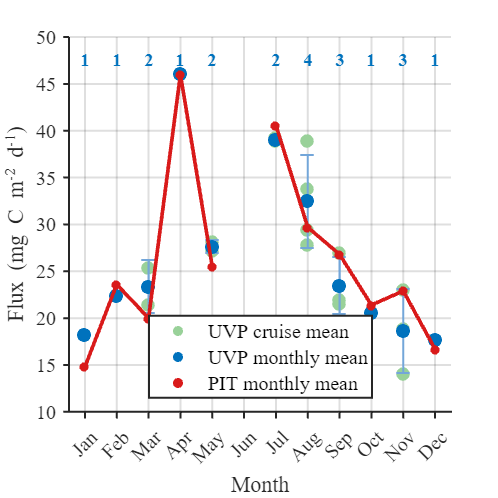

INPUTTING USER SETTINGS


VERIFYING INPUT DATA



Data folder:
F:\Data Exports\Particle Characteristics


Exists: 1



Scripts folder:
F:\White Docs\Matlab Processes\PhD Scripts


Exists: 1



Save directory:
F:\Data Exports\Particle Size Distribution


Exists: 1



Figure repository:
F:\Figure Repository


Exists: 1



Dates file:
F:\HOT_data_imports\project_dates.xlsx


Exists: 1



PIT file:
F:\HOT_data_imports\HOT_PIT_Carb_unQC.xlsx


Exists: 1



Number of files in UVP data folder: 30



First several files:


    {'GRADIENTS_4_particle_characterstics.mat'}
    {'GRADIENTS_5_particle_characterstics.mat'}
    {'HOT_321_particle_characterstics.mat'    }
    {'HOT_322_particle_characterstics.mat'    }
    {'HOT_323_particle_characterstics.mat'    }
    {'HOT_324_particle_characterstics.mat'    }
    {'HOT_325_particle_characterstics.mat'    }
    {'HOT_326_particle_characterstics.mat'    }
    {'HOT_327_particle_characterstics.mat'    }
    {'HOT_328_particle_characterstics.mat'    }



READING PROJECT DATES


Rows in project dates table: 38


Columns in project dates table: 4


    project    cruise     startDate        endDate   
    _______    ______    ____________    ____________

    {'HOT'}     321      {'06082020'}    {'11082020'}
    {'HOT'}     322      {'28082020'}    {'06092020'}
    {'HOT'}     323      {'25092020'}    {'30092020'}
    {'HOT'}     324      {'17112020'}    {'22112020'}
    {'HOT'}     325      {'17122020'}    {'21122020'}



READING PIT DATA


Rows in PIT table: 33


Columns in PIT table: 3


    crn    carb    sd 
    ___    ____    ___

    319    20.2      5
    320    29.6    3.6
    321    32.2    2.7
    322    21.3    2.7
    323    25.5    5.2



CHECKING REQUIRED FUNCTIONS



UVP5_PSD:


F:\Scripts\Flux Code\UVP5_PSD.m



UVP_PIT_Flux_Optimize:


F:\Scripts\Flux Code\UVP_PIT_Flux_Optimize.m


CALCULATING UVP PSD: 0-500 m


PSD computation completed.



PSD calculation finished.


PSD OUTPUT



PSD_data:


  Name              Size              Bytes  Class    Attributes

  PSD_data      14812x11            2669639  table              




First 10 rows of PSD_data:


    bin_center_mm    bin_width_mm    counts_per_liter_per_mm    project    cruise    cast    station       datetime_start           datetime_end        depthStart    depthEnd
    _____________    ____________    _______________________    _______    ______    ____    _______    ____________________    ____________________    __________    ________

       0.10623         0.012849                   0               "H"      "321"      5         2       08-Aug-2020 12:41:36    08-Aug-2020 12:41:36        0           500   
       0.11988         0.014501                   0               "H"      "321"      5         2   


PSD_slopes:


  Name              Size            Bytes  Class    Attributes

  PSD_slopes      322x9             55781  table              




First 10 rows of PSD_slopes:


    Project    Cruise    Cast    Station     Slope        DatetimeStart            DatetimeEnd         depthStart    depthEnd
    _______    ______    ____    _______    _______    ____________________    ____________________    __________    ________

      "H"      "321"       5        2       -3.0334    08-Aug-2020 12:41:36    08-Aug-2020 12:41:36        0           500   
      "H"      "321"       6        2       -3.0646    08-Aug-2020 15:37:50    08-Aug-2020 15:37:50        0           500   
      "H"      "321"       7        2       -3.1205    08-Aug-2020 18:21:30    08-Aug-2020 18:21:30        0           500   
      "H"      "321"       9        2       -3.6817    09-Aug-2

SAVING 0-500 m PSD



PSD saved to:
F:\Data Exports\Particle Size Distribution\FullDepth\PSD_data_0_500_26.mat


VERIFYING SAVED PSD



File exists: 1


File size: 0.13 MB


PSD DATA CHECKS



Number of PSD rows: 14812


Number of unique cruises: 26


Number of unique casts: 22


Minimum particle size: 0.1062 mm


Maximum particle size: 24.4751 mm


Depth range represented:


Minimum depth start: 0.0 m


Maximum depth end: 500.0 m



Available cruises in PSD_data:


    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "328"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "349"
    "350"
    "351"
    "352"
    "353"
    "354"
    "355"
    "356"



CALCULATING PIT DEPTH PSDs FOR OPTIMIZATION



----------------------------------------


PIT optimization PSD: 155-165 m


----------------------------------------


PSD computation completed.


Rows: 14306


Unique cruise-cast combinations: 311


Particle size: 0.1062 to 24.4751 mm


PSD count range: 0 to 1221.84


UVP-PIT OPTIMIZATION + JACKKNIFE


DEPTH RANGE: 155-165 m


PSD file:
F:\Data Exports\Particle Size Distribution\PSD_PIT_155_165.mat



Common UVP/PIT cruises used for optimization:
    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "350"
    "351"
    "352"
    "353"

Number of cruises used: 21

FULL-DATA UVP-PIT OPTIMIZATION
 
 Iteration   Func-count         f(x)         Procedure
     0            1          37.5389         
     1            3          32.7933         initial simplex
     2            5          25.6056         expand
     3            7          16.3521         expand
     4            9          4.85414         expand
     5           11          3.10338         reflect
     6           13          2.11649         contract outside
     7           15          2.11649         contract outside
     8           17          2.11649         contract inside
     9           18          2.11649       

OPTIMIZATION SUMMARY


    depthStart    depthEnd       A          b         SE_A        SE_b      jackknife_mean_A    jackknife_mean_b    jackknife_bias_A    jackknife_bias_b    R2_log_fit      p_log       nCruises
    __________    ________    ________    ______    _________    _______    ________________    ________________    ________________    ________________    __________    __________    ________

       155          165       0.034139    1.7266    0.0040465    0.11052        0.034121             1.726             -0.000365           -0.012033         0.62906      1


Optimization results saved to:
F:\Data Exports\Particle Size Distribution\UVP_PIT_Optimization_AllDepths.mat


UVP FLUX BY DEPTH


    depthStart    depthEnd    depth    fluxMean    fluxSD
    __________    ________    _____    ________    ______

       155          165        160      26.771     8.4113




Overall UVP vs PIT linear regression


------------------------------------


N         = 21


Slope     = 0.777


Intercept = 5.962


R^2       = 0.667


r         = 0.817


p-value   = 6.317e-06


%% ======================================================================== 
% 11. UVP Flux Contribution by Particle Size
%% ========================================================================

% Manually choose which cruises to include
selectedCruises = [337 346 350 351 352 353];


%% 1. Convert cruise identifiers to numeric

if iscell(uvpBinFlux.cruise)
    uvpBinCruise = str2double(uvpBinFlux.cruise);
elseif isstring(uvpBinFlux.cruise)
    uvpBinCruise = str2double(uvpBinFlux.cruise);
else
    uvpBinCruise = uvpBinFlux.cruise;
end


%% 2. Keep only manually selected cruises

selectedData = uvpBinFlux( ...
    ismember(uvpBinCruise,selectedCruises),:);

selectedCruiseNumbers = uvpBinCruise( ...
    ismember(uvpBinCruise,selectedCruises));


%% 3. Get project dates

projCruise = projDates.cruise;

if iscell(projCruise)
    projCruise = cellfun(@str2double,projCruise);
elseif isstring(projCruise)
    projCruise = str2double(projCruise);
end

startDate = datetime( ...
    projDates.startDate, ...
    'InputFormat','ddMMyyyy');


%% 4. Create figure

figure( ...
    'Color','w', ...
    'Units','inches', ...
    'Position',[1 1 7 3.5]);

hold on;


%% 5. Define colorblind-friendly colors

% Colors are intentionally distinct.
% Yellow is the standard MATLAB yellow used in the previous graphs.

colors = [
    0.0000 0.4470 0.7410    % Blue
    0.8500 0.3250 0.0980    % Orange/red
    0.4940 0.1840 0.5560    % Purple
    0.0000 0.6000 0.5000    % Teal
    0.9290 0.6940 0.1250    % MATLAB yellow
    0.6350 0.0780 0.1840    % Dark red
];


%% 6. Plot each selected cruise

nCruises = length(selectedCruises);

legendHandles = gobjects(nCruises,1);
legendLabels = strings(nCruises,1);

for i = 1:nCruises

    cruise = selectedCruises(i);

    % Get data for this cruise
    cruiseIdx = selectedCruiseNumbers == cruise;

    cruiseData = selectedData(cruiseIdx,:);


    %% Remove invalid values

    valid = ~isnan(cruiseData.bin_center_mm) & ...
            ~isnan(cruiseData.uvp_bin_flux) & ...
            cruiseData.bin_center_mm > 0;

    cruiseData = cruiseData(valid,:);


    %% Calculate MEAN flux for each size bin across all casts

    [binGroups, uniqueBins] = findgroups( ...
        cruiseData.bin_center_mm);

    binFlux = splitapply( ...
        @mean, ...
        cruiseData.uvp_bin_flux, ...
        binGroups);


%% Sort by particle size

[binSize,sortIdx] = sort(uniqueBins);

binFlux = binFlux(sortIdx);

% Remove first (smallest) bin
binSize(1) = [];
binFlux(1) = [];



    %% Plot cruise

    legendHandles(i) = plot( ...
        binSize, ...
        binFlux, ...
        '-', ...
        'Color',colors(i,:), ...
        'LineWidth',1.5);


    %% Find date for this cruise

    dateIdx = projCruise == cruise;

    if any(dateIdx)

        cruiseDate = startDate(find(dateIdx,1));

        monthName = datestr(cruiseDate,'mmmm');
        yearName = datestr(cruiseDate,'yyyy');

        % Legend: cruise number + month + year
        legendLabels(i) = sprintf( ...
            '%d (%s %s)', ...
            cruise, ...
            monthName, ...
            yearName);

    else

        legendLabels(i) = sprintf( ...
            '%d', ...
            cruise);

    end

end


%% 7. Set logarithmic x-axis

set(gca,'XScale','log');

xlim([0.1 26]);


%% 8. Axis labels

xlabel( ...
    'Particle Size (mm)', ...
    'FontName','Times New Roman', ...
    'FontSize',12);

ylabel( ...
    'UVP Flux (mg C m^{-2} d^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);


%% 9. Axis formatting

ax = gca;

ax.FontName = 'Times New Roman';
ax.FontSize = 12;
ax.LineWidth = 1.2;

% Remove top and right axes
ax.Box = 'off';

% Ticks outside
ax.TickDir = 'out';

ax.TickLength = [0.015 0.008];

% No grid
grid on;


%% 10. Legend

lgd = legend( ...
    legendHandles, ...
    legendLabels, ...
    'Location','best');

lgd.FontName = 'Times New Roman';
lgd.FontSize = 12;
lgd.Box = 'on';


%% 11. Figure size: 7 inches wide x 3.5 inches tall

set(gcf, ...
    'Units','inches', ...
    'Position',[1 1 7 3.5]);

set(gcf, ...
    'PaperUnits','inches', ...
    'PaperPosition',[0 0 7 3.5]);


%% 12. Save figure

fileName = 'UVP Flux by Particle Size';

exportgraphics( ...
    gcf, ...
    fullfile(saveFolder,[fileName '.png']), ...
    'Resolution',600);


hold off;

%% ========================================================================
%  12. UVP PARTICLE SIZE DISTRIBUTION
%% ========================================================================
 
% Cruise-level mean PSDs:
%
%       Individual cruise means = light grey
%       Mean across cruises     = black

PLOTTING UVP PARTICLE SIZE DISTRIBUTION



%% 1. Define cruises to exclude

excludePSDcruises = ["328"];

fprintf('\nCruises excluded from PSD plot:\n');


Cruises excluded from PSD plot:


disp(excludePSDcruises');

328




%% 2. Remove excluded cruises

cruiseID_all = string(PSD_data.cruise);

excludeIdx = ismember( ...
    cruiseID_all, ...
    excludePSDcruises);

fprintf('Number of PSD rows before exclusion: %d\n', ...
    height(PSD_data));

Number of PSD rows before exclusion: 14812



fprintf('Number of PSD rows excluded: %d\n', ...
    sum(excludeIdx));

Number of PSD rows excluded: 184



PSD_plot = PSD_data(~excludeIdx,:);

fprintf('Number of PSD rows after exclusion: %d\n', ...
    height(PSD_plot));

Number of PSD rows after exclusion: 14628




%% 3. Extract PSD variables

cruiseID = string(PSD_plot.cruise);

ESD_data = PSD_plot.bin_center_mm;

counts_data = PSD_plot.counts_per_liter_per_mm;


%% 4. Remove invalid values

valid = ...
    isfinite(ESD_data) & ...
    isfinite(counts_data) & ...
    ESD_data > 0 & ...
    counts_data > 0;

cruiseID = cruiseID(valid);

ESD_data = ESD_data(valid);

counts_data = counts_data(valid);


%% 5. Get unique cruises

uniqueCruises = unique(cruiseID);

nCruises = length(uniqueCruises);

fprintf('\nNumber of cruises included: %d\n', ...
    nCruises);


Number of cruises included: 25



fprintf('\nIncluded cruises:\n');


Included cruises:


disp(uniqueCruises);

    "321"
    "322"
    "323"
    "324"
    "325"
    "326"
    "327"
    "335"
    "336"
    "337"
    "339"
    "341"
    "342"
    "344"
    "345"
    "346"
    "347"
    "349"
    "350"
    "351"
    "352"
    "353"
    "354"
    "355"
    "356"





%% 6. Calculate cruise-level mean PSDs

% Each cruise gets its own mean PSD.
%
% If a cruise has multiple profiles/casts contributing to a given
% particle-size bin, those observations are averaged within the cruise.
%
% These cruise-level means are then used to calculate the overall
% study mean.

cruiseESD = cell(nCruises,1);

cruiseCounts = cell(nCruises,1);


for i = 1:nCruises

    thisCruise = uniqueCruises(i);

    fprintf('Calculating mean PSD for cruise %s...\n', ...
        thisCruise);

    % Select current cruise

    idx = cruiseID == thisCruise;

    thisESD = ESD_data(idx);

    thisCounts = counts_data(idx);


    % Group observations by ESD bin

    [binGroups,binESD] = findgroups(thisESD);


    % Calculate mean count for each ESD bin

    binMeanCounts = splitapply( ...
        @mean, ...
        thisCounts, ...
        binGroups);


    % Sort by particle size

    [binESD,sortIdx] = sort(binESD);

    binMeanCounts = binMeanCounts(sortIdx);


    % Store cruise-level PSD

    cruiseESD{i} = binESD;

    cruiseCounts{i} = binMeanCounts;

end

Calculating mean PSD for cruise 321...
Calculating mean PSD for cruise 322...
Calculating mean PSD for cruise 323...
Calculating mean PSD for cruise 324...
Calculating mean PSD for cruise 325...
Calculating mean PSD for cruise 326...
Calculating mean PSD for cruise 327...
Calculating mean PSD for cruise 335...
Calculating mean PSD for cruise 336...
Calculating mean PSD for cruise 337...
Calculating mean PSD for cruise 339...
Calculating mean PSD for cruise 341...
Calculating mean PSD for cruise 342...
Calculating mean PSD for cruise 344...
Calculating mean PSD for cruise 345...
Calculating mean PSD for cruise 346...
Calculating mean PSD for cruise 347...
Calculating mean PSD for cruise 349...
Calculating mean PSD for cruise 350...
Calculating mean PSD for cruise 351...
Calculating mean PSD for cruise 352...
Calculating mean PSD for cruise 353...
Calculating mean PSD for cruise 354...
Calculating mean PSD for cruise 355...
Calculating mean PSD for cruise 356...


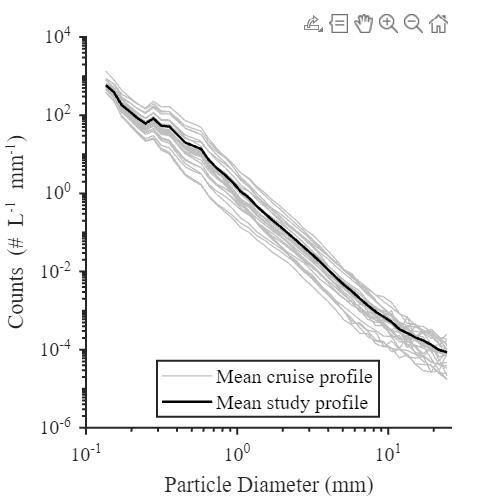



%% 7. Determine common ESD bins

uniqueESD = unique(ESD_data);

uniqueESD = sort(uniqueESD);


%% 8. Calculate mean PSD across cruises

% The black line is calculated from the cruise-level means.
%
% Therefore every cruise has equal weighting.
%
% A cruise with many profiles does NOT receive more weight than a
% cruise with fewer profiles.

meanPSD = nan(size(uniqueESD));


for b = 1:length(uniqueESD)

    thisESD = uniqueESD(b);

    cruiseValues = nan(nCruises,1);


    for i = 1:nCruises

        % Find this ESD bin within the current cruise

        idx = abs(cruiseESD{i} - thisESD) < 1e-10;


        if any(idx)

            cruiseValues(i) = ...
                cruiseCounts{i}(find(idx,1));

        end

    end


    % Calculate mean across cruises

    meanPSD(b) = mean( ...
        cruiseValues, ...
        'omitnan');

end


%% 9. Create figure

figure( ...
    'Color','w', ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

hold on;


%% 10. Plot individual cruise mean profiles

% The first ACTUAL grey cruise profile is used as the legend handle.
% No dummy line is created.

hCruiseMean = gobjects(1);


for i = 1:nCruises

    thisESD = cruiseESD{i};

    thisCounts = cruiseCounts{i};


    % Remove invalid values

    valid = ...
        isfinite(thisESD) & ...
        isfinite(thisCounts) & ...
        thisESD > 0 & ...
        thisCounts > 0;


    % Plot actual cruise profile

    h = plot( ...
        thisESD(valid), ...
        thisCounts(valid), ...
        '-', ...
        'Color',[0.75 0.75 0.75], ...
        'LineWidth',0.8);


    % Use first actual cruise line as legend entry

    if i == 1

        hCruiseMean = h;

        hCruiseMean.DisplayName = ...
            'Mean cruise profile';

    else

        % Keep other cruise profiles out of legend

        h.HandleVisibility = 'off';

    end

end


%% 11. Plot mean across all cruises

validMean = ...
    isfinite(uniqueESD) & ...
    isfinite(meanPSD) & ...
    uniqueESD > 0 & ...
    meanPSD > 0;


hStudyMean = plot( ...
    uniqueESD(validMean), ...
    meanPSD(validMean), ...
    '-', ...
    'Color',[0 0 0], ...
    'LineWidth',1.5, ...
    'DisplayName','Mean study profile');


%% 12. Set logarithmic axes

set(gca, ...
    'XScale','log', ...
    'YScale','log');


%% 13. Set x-axis limits

xlim([ESDmin ESDmax]);


%% 14. Axis labels

xlabel( ...
    'Particle Diameter (mm)', ...
    'FontName','Times New Roman', ...
    'FontSize',12);

ylabel( ...
    'Counts (# L^{-1} mm^{-1})', ...
    'FontName','Times New Roman', ...
    'FontSize',12);


%% 15. Axis formatting

ax = gca;

ax.FontName = 'Times New Roman';

ax.FontSize = 12;

ax.LineWidth = 1.2;

ax.Box = 'off';

ax.TickDir = 'out';

ax.TickLength = [0.015 0.008];


%% 16. No grid lines

grid off;


%% 17. Legend

lgd = legend( ...
    [hCruiseMean hStudyMean], ...
    {'Mean cruise profile','Mean study profile'}, ...
    'Location','best');

lgd.FontName = 'Times New Roman';

lgd.FontSize = 12;

lgd.Box = 'on';


%% 18. Set exact figure size

set(gcf, ...
    'Units','inches', ...
    'Position',[1 1 6 6]);

set(gcf, ...
    'PaperUnits','inches', ...
    'PaperPosition',[0 0 6 6]);

set(gcf, ...
    'PaperSize',[6 6]);


%% 19. Save figure

fileName = ...
    'UVP Particle Size Distribution Excluding Cruise 328';

exportgraphics( ...
    gcf, ...
    fullfile(saveFolder,[fileName '.png']), ...
    'Resolution',600);


%% 20. Finish

hold off;



fprintf('\nPSD figure saved to:\n%s\n', ...
    fullfile(saveFolder,[fileName '.png']));


PSD figure saved to:
F:\Figure Repository\UVP Particle Size Distribution Excluding Cruise 328.png



fprintf('\nFigure size: 6 x 6 inches\n');


Figure size: 6 x 6 inches



fprintf('Font size: 12 pt\n');

Font size: 12 pt



fprintf('Resolution: 600 dpi\n');

Resolution: 600 dpi


PSD PLOT COMPLETE
